**PRAKTIKUM ROBOTIKE - segmentacija slike**

%------------------------------
metoda_slike_1 = 1

metoda_slike_1 = 1

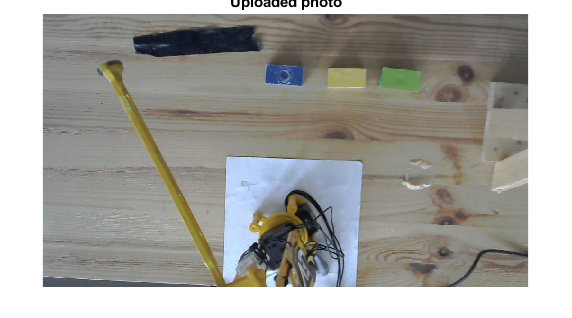

%-----------------------------
switch metoda_slike_1
    case 0
        camera_info = imaqhwinfo('winvideo')
        
        camera_info.DeviceInfo.DeviceID
        camera_info.DeviceInfo.DefaultFormat
        camera_info.DeviceInfo.SupportedFormats
        
        video_obj = videoinput('winvideo', 1,'MJPG_1280x960');
        video_obj.ReturnedColorSpace = 'rgb';
        
        % start video object
        start(video_obj);
        
        %% assignment 3 - getting the image from the camera
        img = getdata(video_obj);
        
        % extract RGB parts (discard A channel)
        img = img(:, :, (1:3));
        
        % check image 
        imshow(img); title('Camera output');
        
        stop(video_obj);
    case 1
        img = imread('D:\Documents\Fer\Praktikum robotike\Robot izrada\Programi\slika_kockice_2.jpg');
        imshow(img); title('Uploaded photo');
end

**Filter image**

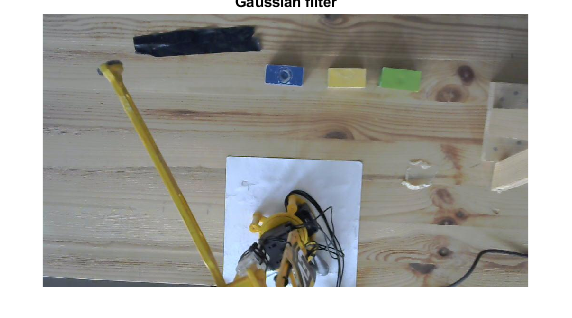

gauss_filt = fspecial('gaussian', [1,1], 5);
img_filt= imfilter(img, gauss_filt);
figure;
imshow(img_filt); title('Gaussian filter');

imwrite(img,'proba7.jpg')

%% 
img_hsv = rgb2hsv(img_filt);
img_gray = rgb2gray(img_filt);
I = img_hsv

I = I(:,:,1) =

  Columns 1 through 999

    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.4167    0.4167    0.4167    0.4167    0.4167    0.4167    0.6111    0.6111    0.6111    0.6111    0.6333    0.6333    0.6333    0.6333    0.6389    0.6333    0.6333    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.6111    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.5333    0.4167    0.4167    0.4167    0.4167    0.4167    0.4167    0.6111    0.6111    0.6111    0.6111    0.6333    0.6333    0.6333    0.6333    0.6389    0.6333    0.2778    0.2333    0.2333    0.2333    0.2333    0.2333    0.2333    0.2333    0.2333    0.2333    0.2333    0.2333    0.2333    0.2333    0.2333    0.233

**Color treshold**

%%---unos boje kockice--------------------------
n = 1

n = 1

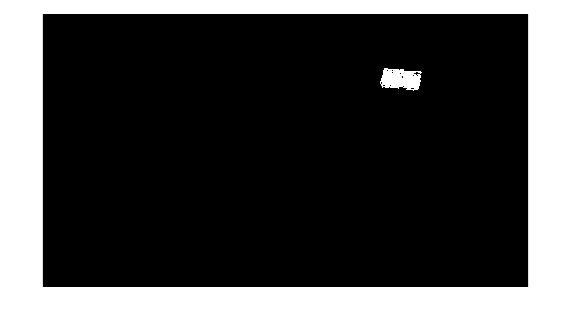

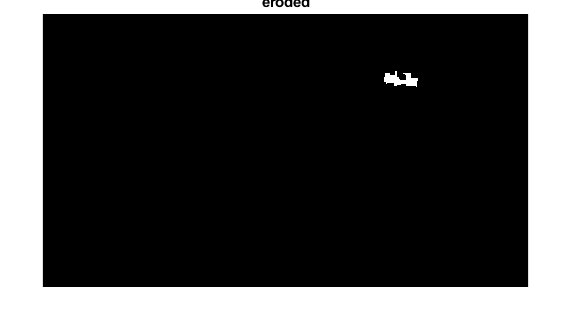

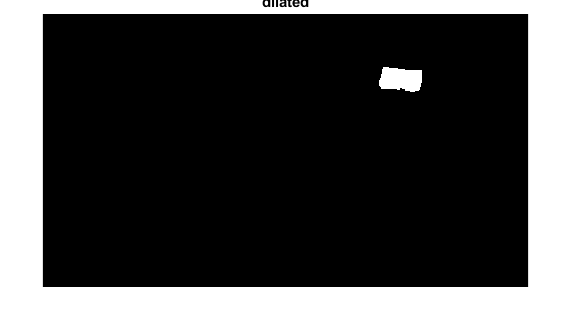

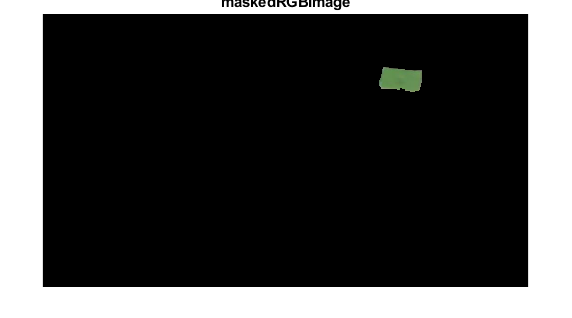

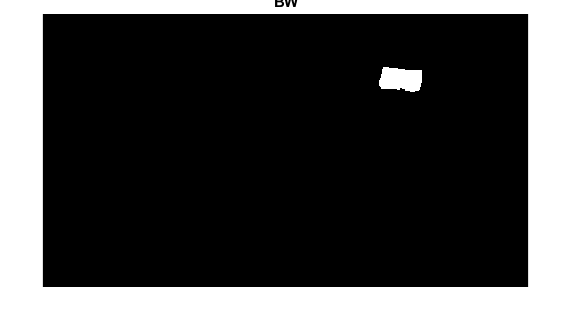

%%----------------------------------------------

switch n
    %%Yellow
    case -1
        % Define thresholds for channel 1 based on histogram settings
        channel1Min = 0.09;
        channel1Max = 0.19;
        
        % Define thresholds for channel 2 based on histogram settings
        channel2Min = 0.21;
        channel2Max = 0.54;
        
        % Define thresholds for channel 3 based on histogram settings
        channel3Min = 0.6;
        channel3Max = 0.7;

        sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
            (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
            (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
        BW = sliderBW;
        imshow(BW);
        figure;

        se = strel('square', 6);
        eroded = imerode(BW, se);
        imshow(eroded);title('eroded');
        figure;
        se = strel('square', 2);
        dilated = imdilate(BW, se);
        imshow(dilated);title('dilated')
        figure;

        %%----------ako eroded/dilated pomaze---------
        BW= eroded;
        %---------------------------------------------
        
        % Initialize output masked image based on input image.
        maskedRGBImage = img_filt;
        
        % Set background pixels where BW is false to zero.
        maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
        
        
        figure();imshow(maskedRGBImage);title('maskedRGBImage');
        figure();imshow(BW);title('BW');

    %%BLUE
    case 0
         % Define thresholds for channel 1 based on histogram settings
        channel1Min = 0.58;
        channel1Max = 0.63;
        
        % Define thresholds for channel 2 based on histogram settings
        channel2Min = 0.3;
        channel2Max = 0.77;
        
        % Define thresholds for channel 3 based on histogram settings
        channel3Min = 0.31;
        channel3Max = 0.72;

        sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
            (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
            (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
        BW = sliderBW;
        imshow(BW);
        figure;
        se = strel('square', 4);
        eroded = imerode(BW, se);
        imshow(eroded);title('eroded');
        figure;
        se = strel('square', 5);
        dilated = imdilate(BW, se);
        imshow(dilated);title('dilated')
        figure;

        %%----------ako eroded/dilated pomaze---------
        BW= eroded;
        %---------------------------------------------
        
        % Initialize output masked image based on input image.
        maskedRGBImage = img_filt;
        
        % Set background pixels where BW is false to zero.
        maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
        
        
        figure();imshow(maskedRGBImage);title('maskedRGBImage');
        figure();imshow(BW);title('BW');

    %%GREEN
    case 1
        % Define thresholds for channel 1 based on histogram settings
        channel1Min = 0.26;
        channel1Max =0.4;
        
        % Define thresholds for channel 2 based on histogram settings
        channel2Min =0.22;
        channel2Max =0.48;
        
        % Define thresholds for channel 3 based on histogram settings
        channel3Min =0.52;
        channel3Max =0.58;
        sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
            (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
            (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
        BW = sliderBW;
        imshow(BW);
        figure;
        se = strel('square', 10);
        eroded = imerode(BW, se);
        imshow(eroded);title('eroded');
        figure;
        se = strel('square', 5);
        dilated = imdilate(BW, se);
        imshow(dilated);title('dilated')
        figure;

        %%----------ako eroded/dilated pomaze---------
        BW= dilated;
        %---------------------------------------------
        
        
        % Initialize output masked image based on input image.
        maskedRGBImage = img_filt;
        
        % Set background pixels where BW is false to zero.
        maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
        
        
        figure();imshow(maskedRGBImage);title('maskedRGBImage');
        figure();imshow(BW);title('BW');


    %%BLACK
    case 2
        % Define thresholds for channel 1 based on histogram settings
        channel1Min = 0.41;
        channel1Max =0.7;
        
        % Define thresholds for channel 2 based on histogram settings
        channel2Min =0.26;
        channel2Max =0.1;
        
        % Define thresholds for channel 3 based on histogram settings
        channel3Min =0.008;
        channel3Max =0.43;
        sliderBW = (I(:,:,1) >= channel1Min ) & (I(:,:,1) <= channel1Max) & ...
            (I(:,:,2) >= channel2Min ) & (I(:,:,2) <= channel2Max) & ...
            (I(:,:,3) >= channel3Min ) & (I(:,:,3) <= channel3Max);
        BW = sliderBW;
        imshow(BW);
        figure;

        se = strel('square', 10);
        eroded = imerode(BW, se);
        imshow(eroded);title('eroded');
        figure;
        se = strel('square', 5);
        dilated = imdilate(BW, se);
        imshow(dilated);title('dilated')
        figure;

        %%----------ako eroded/dilated pomaze---------
        BW= BW;
        %---------------------------------------------
        
        % Initialize output masked image based on input image.
        maskedRGBImage = img_filt;
        
        % Set background pixels where BW is false to zero.
        maskedRGBImage(repmat(~BW,[1 1 3])) = 0;
        
        
        figure();imshow(maskedRGBImage);title('maskedRGBImage');
        figure();imshow(BW);title('BW');

    otherwise
        disp('other value')
end

**Center of the mass position**

bw_x = im2bw(BW);

bw_x = imfill(BW,'holes');
[bwLabel, num]= bwlabel(bw_x);

s=regionprops(bwLabel,'BoundingBox')

s = struct with fields:
    BoundingBox: [709.5000 111.5000 92 53]



center=regionprops(bwLabel,'Centroid')

center = struct with fields:
    Centroid: [755.8418 138.2836]


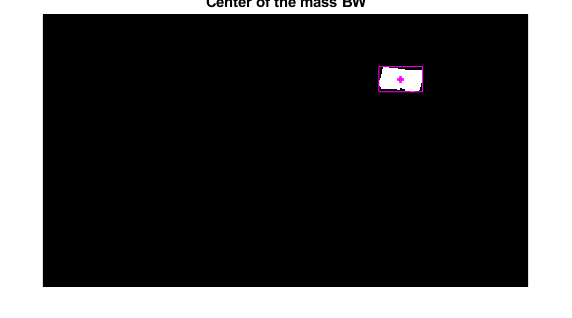

imshow(BW);
hold on
%---ENTER WICH CENTROID------
i =1;
j = 1;
%----------------------------
rectangle('Position',s(i).BoundingBox,'Edgecolor', 'magenta')
hold on
plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
title("Center of the mass BW")
hold off

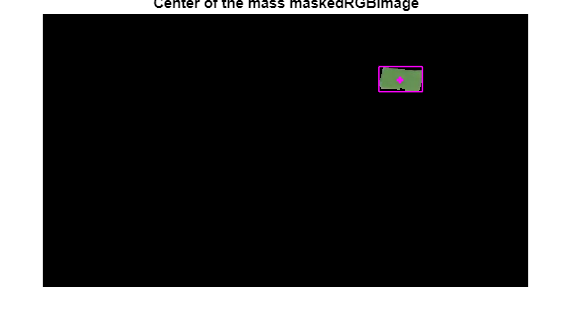


imshow(maskedRGBImage)
hold on
rectangle('Position',s(i).BoundingBox,'Edgecolor', 'magenta')
hold on
plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
title("Center of the mass maskedRGBImage")
hold off

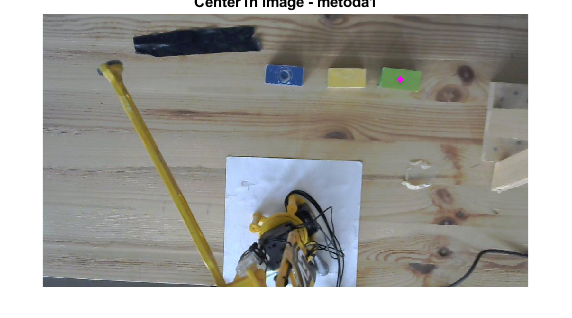


imshow(img)
hold on
plot(center(j).Centroid(1),center(j).Centroid(2), 'm+', 'MarkerSize', 5, 'LineWidth', 2);
title("Center in image - metoda1")
hold off

**Save center of the mass**

if n==-1
    x_yellow = center(i).Centroid(1)
    y_yellow = center(i).Centroid(2)
end

if n==0
    x_blue = center(i).Centroid(1)
    y_blue = center(i).Centroid(2)
end

if n==1
    x_green = center(i).Centroid(1)
    y_green = center(i).Centroid(2)
end

if n==2
    x_black = center(i).Centroid(1)
    y_black = center(i).Centroid(2)
end

**Metoda za prepoznavanje uzoraka**

%-----------------------
metoda_slike_2 = 1
%-----------------------
switch metoda_slike_2
    case -1
        %slika segmentirana bojom
        I = maskedRGBImage;
    case 0
        %početna slika iz skripte
        I = img_filt;
    case 1
        %upload nove skripte
        I = imread('D:\_Documents\Fer\Praktikum robotike\slika_kockice_8.jpg');
end

%------------------------
kockica = -1
angle = -45
%------------------------

switch kockica
    case -1
        %%Yellow
        yellow = imread('D:\_Documents\Fer\Praktikum robotike\slika_kockice_2_zuta.jpg');
        yellow_rotated = imrotate(yellow, angle);
        yellow_location = find_object(I,yellow_rotated);
        x1_yellow = yellow_location(1)
        y1_yellow = yellow_location(2)
     case 0
        %%BLUE
        blue = imread('D:\_Documents\Fer\Praktikum robotike\slika_kockice_2_plava.jpg');
        blue_rotated = imrotate(blue, angle);
        blue_location = find_object(I,blue_rotated);
        x1_blue = blue_location(1)
        y1_blue = blue_location(2)
    case 1
        %%GREEN
        green = imread('D:\_Documents\Fer\Praktikum robotike\slika_kockice_2_zelena.jpg');
        green_rotated = imrotate(green, angle);
        green_location = find_object(I,green_rotated);
        x1_green = green_location(1)
        y1_green = green_location(2)
   
    case 2
        %%BLACK
        black = imread('D:\_Documents\Fer\Praktikum robotike\slika_kockice_2_crna.jpg');
        black_location = find_object_black(I,black);
        x1_black = black_location(1)
        y1_black = black_location(2)
        x2_black = black_location(3)
        y2_black = black_location(4)
        x3_black = black_location(5)
        y3_black = black_location(6)
end

if kockica==-1

    x_mean_yellow = (x_yellow + x1_yellow)/2
    y_mean_yellow = (y_yellow + y1_yellow)/2

    imshow(I)
    hold on
    plot(x_mean_yellow,y_mean_yellow, 'm+', 'MarkerSize', 5, 'LineWidth', 2);
    title("Center in image - mean")
    hold off
end

if kockica==0

    x_mean_blue = (x_blue + x1_blue)/2
    y_mean_blue = (y_blue+ y1_blue)/2

    imshow(I)
    hold on
    plot(x_mean_blue,y_mean_blue, 'm+', 'MarkerSize', 5, 'LineWidth', 2);
    title("Center in image - mean")
    hold off

end

if kockica==1

    x_mean_green = (x_green + x1_green)/2
    y_mean_green = (y_green+ y1_green)/2

    imshow(I)
    hold on
    plot(x_mean_green ,y_mean_green, 'm+', 'MarkerSize', 5, 'LineWidth', 2);
    title("Center in image - mean")
    hold off
    
end

if kockica==2
    x1_black = center(i).Centroid(1)
    y1_black = center(i).Centroid(2)
end



function location= find_object(image,T)
    imshow(image)
    figure
    I= rgb2gray(image);
    [Ir, Ic]=size(I);
    figure(1);
    imshow(I);
    T= rgb2gray(T);
    figure(2)
    imshow(T);
    [Tr, Tc]=size(T);
    R = normxcorr2(T,I);
    R = imcrop(R,[Tc Tr Ic Ir]);
    [r, c, v] = find(R==(max(max(R))))
    RGB = insertShape(I, "rectangle", [c r Tc Tr], "LineWidth", 3,"Color","magenta");
    figure(3)
    imshow(RGB);
    hold on
    plot(c+Tc/2,r+Tr/2, 'm+', 'MarkerSize', 5, 'LineWidth', 2);
    hold off
    imshow(image)
    hold on
    plot(c+Tc/2,r+Tr/2, 'm+', 'MarkerSize', 5, 'LineWidth', 2);
    title("Center in image - metoda 2")
    hold off
    location = [c+Tc/2, r+Tr/2];

end

function location= find_object_black(I,T)
    I= rgb2gray(I);
    [Ir, Ic]=size(I);
    figure(1);
    imshow(I);
    T= rgb2gray(T);
    figure(2)
    imshow(T);
    [Tr, Tc]=size(T);
    R = normxcorr2(T,I);
    R = imcrop(R,[Tc Tr Ic Ir]);
    [r, c, v] = find(R==(max(max(R))))
    RGB = insertShape(I, "rectangle", [c r Tc Tr], "LineWidth", 3,"Color","magenta");
    figure(3)
    %optimalno 0.165
    center_1_x = c+Tc*0.165
    %optimalno 0.495
    center_1_y = r+Tr*0.495

    center_2_x = c+Tc*0.495
    center_2_y = r+Tr*0.495

    %optimalno 0.825
    center_3_x = c+Tc*0.825
    %optimalno 0.495
    center_3_y = r+Tr*0.495
    imshow(RGB);
    hold on
    plot(center_1_x,center_1_y, 'm+', 'MarkerSize', 5, 'LineWidth', 2);
    hold on
    plot(center_2_x,center_2_y, 'm+', 'MarkerSize', 5, 'LineWidth', 2);
    hold on
    plot(center_3_x,center_3_y, 'm+', 'MarkerSize', 5, 'LineWidth', 2);
    hold off
    location = [[center_1_x,center_1_y], [center_2_x,center_2_y], [center_3_x,center_3_y]];

end
